# Effect of Haar-Based Compression on Virtual Reality Images

### Final Project for Math 179 (Spring 2019)

### Yoshiki Takashima (A14691595)

## 1. Overview

Traditionally, an image represents a 2-Dimensional uniform grid of pixels. On the other hand, with the rise of Virtual Reality (VR) technologies, various methods were created to project a 3-Dimensional sphere onto one or more images. Furthermore, due to the mathematical difficulty of projecting a 3-Dimensional image onto 2-Dimensional data, these images are naturally skewed. In these use cases, the image no longer represents the traditional rectangular data, even as the encoding is the same. I will explore the effect of traditional (2-Dimensional) compression techniques on Equirectangular VR images. Furthremore, we will implement the previously mitigations proposed for Equirectangular images. To provide comparison with other methods, we will also compress VR images mapped in the Cube Map format and the recently proposed Equiangular Cube Map format. We will end with comparison of compression artifacts between various mapping formats and the theory behind why these artifacts occur.

Before we start, let us introduce the mapping formats. In its natural format, the VR image is a sphere. First, the **Equirectangular Mapping** is the most simple mapping. This mapping projects the spere onto a cylinder and rolls it out, resulting in an image that is stretched at the margins. Second is the **Cube Mapping**. This mapping projects the sphere onto a cube, and cuts out the image to a set of 6 images representing the views of each direction. In addition to the above two, which we will experiment with, various other mappings have been presented, including the Equiangular Cube Mapping developed by Google(3) and pyramid mapping used by Facebook(4). The former is a method of more equally distributing pixels for each area of the sphere, and the latter is format of VR that does not require rendering on site, instead having multiple viewports from which the user switches between.

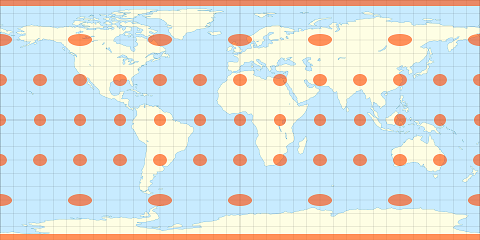

**Above**: Equirectangular Mapping of the world map.

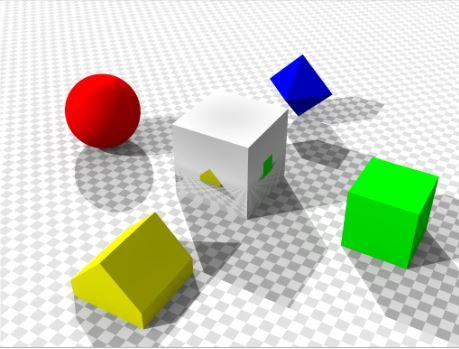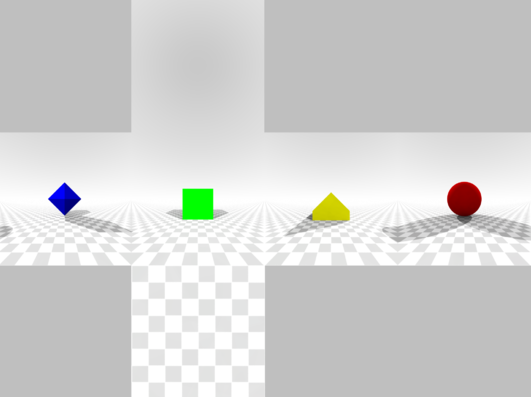

**Above**: A VR environment (left) and a cube mapping using the middle cube as the perspective (right).

Project Content and Artifacts:

- Matlab implementation of discussed compression methods.

- Matlab implementation of converters between formats.

- Comparison of compression artifacts in various formats.

Note: A custom HTML based virtual reality viewers are also included. However, this uses libraries/copied code heavily and should not be counted for the project.

## 2. Recent and Related Works

Most of the recent works in this field date back 2016~18 period, occuring simulataniously with the mass commercialization of VR technologies. As noted before, Google's Equiangular Cube Mapping (3) was a direct response to resolution issues in VR images with application in video streams. By enforcing the equiangular property on the sampling, this technique ensures that the information is more equally distributed. The pyramidal mapping proposed by Facebook (4) converts Equirectangular video into "30 viewports, and ... create five different resolutions for each stream," allowing an approximately smooth transition between the viewports. 

For standards, Moving Picture Experts Group's Omnidirectional Media Format (MPEG-OMAF) standard, albeit more generally oriented toward VR video streams, is one standard that use packing based on image regionand adaptive compression using other factors like the user's head position(1,2). While their format is oriented towards integrating VR video streams into the standard MPEG video stream while maintaining quality, I will apply their repacking techniques to a more basic setting of still images and naive haar threshold compression.

## 3. Pipeline Setup and Formats

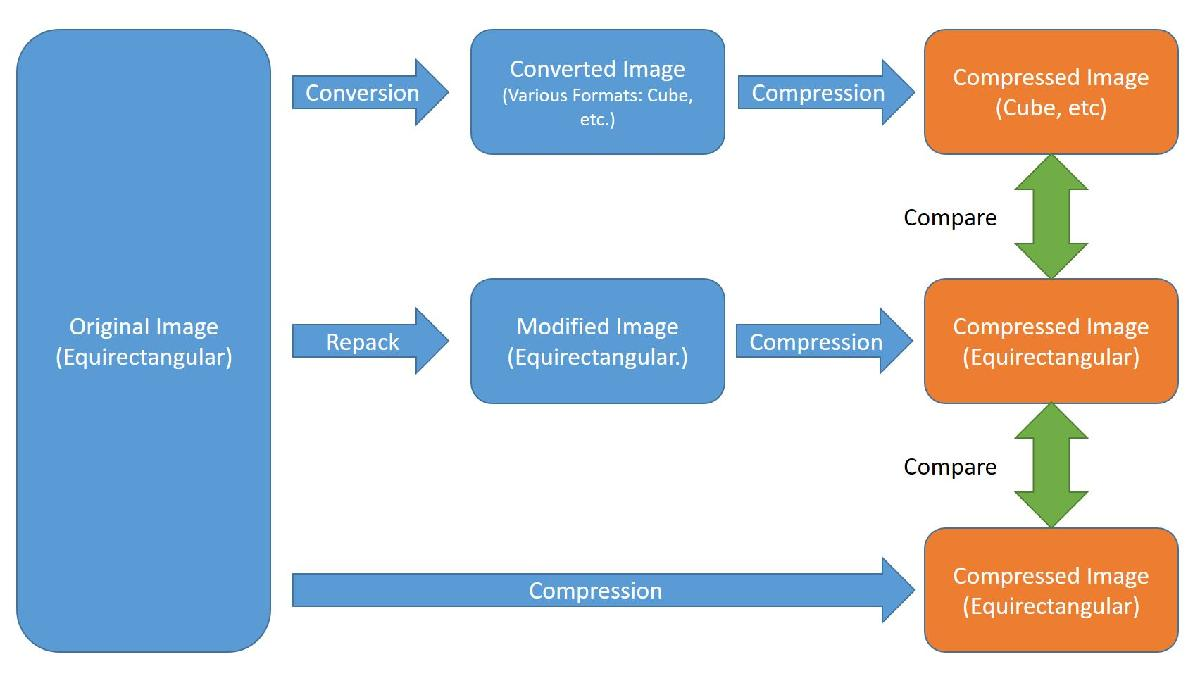

Since we are comparing quality, we must follow a standard procedure for consistency. All images we deal with are in JPEG format and resized to powers of 2. Furthermore, they will be originally in the Equirectangular mapping, and converted to other mappings if necessary. This is because this is the most widely available format for me. Comparisons will be done between the various compressed images in the VR viewer (filename.html). 

## 4. Equirectangular Mapping

First, let us try to apply compression naively. We will simply take the image and do a Haar-based elimination of detail for each RGB channel. The compression ratio here is 5:1 and we add noise to remove the compression effects. 

clear;
in = imread('Viewers/Original360/SkatePark.jpg');
image = in;

[image(:,:,1), sB1, sA1] = Compression(image(:,:,1),0.9);
[image(:,:,2), sB2, sA2] = Compression(image(:,:,2),0.9);
[image(:,:,3), sB3, sA3] = Compression(image(:,:,3),0.9);

d1 = (sB1 - sA1) / sB1;
d2 = (sB2 - sA2) / sB2;
d3 = (sB3 - sA3) / sB3;

imwrite(image, 'Viewers/Output360/SkatePark.jpg');
imshow([image;in]);
title("Eliminated " + num2str(100*mean([d1,d2,d3])) + "% of the image");

**Below: **The top image is the compressed image and the bottom is the original. Visually comparing between the pictures, this looks okay. 

However, when we view this image in the VR viewer, we see a significant difference in quality. Below: the left image is the original and the right is the compressed version.

gr1 = imread('Resources/SkatePark_Original.png');
gr2 = imread('Resources/SkatePark_Compress-Only.png');
imshow([gr1,gr2]);

This, of course, is still better than simply shrinking the image by a factor of 10.

Because the images are skewed by the mapping, the loss of quality is harder to detect. Compression artifacts generated in image before 3D projection is more pronounced. From a more theoritical perspective, this is because the amount of information spent to represent a region of same region is different depending on the distance of that region from the equator. A strip at the middle, representing the entire region around the equator, takes up as much information in 2D as a strip of equal size near the poles, where the 3D area it represents is quite small. Because of such, we note here that the region near the poles do not experience the same compression artifacts.

gr3 = imread('Resources/SkatePark_Comp_NearPole.png');
imshow(gr3);

This skew in the information-to-region ratio can be mitigated using the repacking method proposed in the MPEG OMAF standard. This technique works by resampling the image so that less bits are used for the polar regions, and more bits are used for the equatorial regions. The below is a rough idea of what this represents.

gr4 = imread('Resources/Repack.png');
imshow(gr4);

We first begin by noting that each pixel in the equirectangular representaton represents a point in the angular coorinate. Assign the coordinates so that the area covered by the top and bottom strips are propotional to the area covered by the corresponding region on the sphere. We will use a nearest-neighbor adjustment to resize the image.

Using polar coordinates, we see calculate the area allotted for each region. Let $M$be the ratio of the marginheight to the total height in the original picture. Margins exist at the top and bottom, each of that height. Circumference of each section is $2\pi y$, where $y$ is the height. Thus, we know $y=r*\mathrm{sin}\left(\theta \right)$. The projected boundary of this ring is $r*\Delta \theta$. We integrate that to get $2\int_0^{\pi M} 2\pi r\mathrm{sin}\left(\theta \right)\left(\mathrm{rd}\theta \right)=4\pi r^2 {\left\lbrack -\mathrm{cos}\left(\theta \right)\right\rbrack }_0^{\pi M} =4\pi r^2 \left\lbrack -\mathrm{cos}\left(\pi M\right)-\left(-\mathrm{cos}\left(0\right)\right)\right\rbrack =4\pi r^2 \left\lbrack 1-\mathrm{cos}\left(\pi M\right)\right\rbrack$. Since we are looking for the ratio, we divide this by $4\pi r^2$, the overall area of the sphere. Thus, we get that, in the remapped image, to achieve a more even density, the margin regions should constitute $\left\lbrack 1-\mathrm{cos}\left(\pi M\right)\right\rbrack$ of the total area for some $M\in \left\lbrack 0,0\ldotp 5\right\rbrack$. This is implemented in the remapper.

As with the naive case, the compression ratio is 10:1. The repacking parameters 0.4 and 0.4 respectively represent margin size (ratio to height) and pole region repack ratio (ratio to area)

clear;
image = imread('Viewers/Original360/SkatePark.jpg');

rImg = Repack(image, 0.4, 0.4);
[rImg(:,:,1), sB1, sA1] = Compression(rImg(:,:,1),0.9); %Best up to now 0.4, 0.4
[rImg(:,:,2), sB2, sA2] = Compression(rImg(:,:,2),0.9);
[rImg(:,:,3), sB3, sA3] = Compression(rImg(:,:,3),0.9);
output = Unpack(rImg,0.4, 0.4);

d1 = (sB1 - sA1) / sB1;
d2 = (sB2 - sA2) / sB2;
d3 = (sB3 - sA3) / sB3;

imwrite(output,'Viewers/Output360/SkatePark_RepackComp.jpg');
disp("Eliminated " + num2str(100*mean([d1,d2,d3])) + "% of the image");

We can see modest imrovemet in resolution, especially around corners where color changes significantly. 

gr1 = imread('Resources/SkatePark_Compress-Only.png');
gr2 = imread('Resources/SkatePark_Compress-Repack.png');
imshow([gr1,gr2]);
title("Compression only (LEFT) and Repack Compression (RIGHT)");

Note the smoothness of the platform and its shadow in the repack-compress image, compared to the naively compressed version.

Let us consider an alternative to the remapping technique: nonlinear thresholding in compresson. To calculate the compression rates for each 8x8 region, we will use a bell curve, in this case, the derivative of the sigmoid $\sigma'(x) = \sigma(x)(1 - \sigma(x))$(By previous knowledge(5)), where the sigmoid is $\sigma(x) = \frac{1}{1 - e^{-x}}$.

clear;
image = imread('Viewers/Original360/SkatePark.jpg');

[image(:,:,1), sB1, sA1] = NonUnifCompression(image(:,:,1),1,1,0);
[image(:,:,2), sB2, sA2] = NonUnifCompression(image(:,:,2),1,1,0);
[image(:,:,3), sB3, sA3] = NonUnifCompression(image(:,:,3),1,1,0);

d1 = (sB1 - sA1) / sB1;
d2 = (sB2 - sA2) / sB2;
d3 = (sB3 - sA3) / sB3;

imwrite(image, 'Viewers/Output360/SkatePark_BellThresh.jpg');

disp("Eliminated " + num2str(100*mean([d1,d2,d3])) + "% of the image");

Eliminated 64.2862% of the image


## 5. Cube Mapping

Finally, we will discuss cube mapping. 

## 6. Comparisons

## 7. Conclusion

## 8. References

- [https://www.vr-if.org/wp-content/uploads/VRSTD-01-MPEG-OMAF-Youngkwon-Lim.pdf](https://www.vr-if.org/wp-content/uploads/VRSTD-01-MPEG-OMAF-Youngkwon-Lim.pdf)

- [https://pdfs.semanticscholar.org/113d/0d0b44f5fc9ef52120cb57107626b1d5f69c.pdf](https://pdfs.semanticscholar.org/113d/0d0b44f5fc9ef52120cb57107626b1d5f69c.pdf)

- [https://blog.google/products/google-ar-vr/bringing-pixels-front-and-center-vr-video/](https://blog.google/products/google-ar-vr/bringing-pixels-front-and-center-vr-video/)

- [https://code.fb.com/virtual-reality/next-generation-video-encoding-techniques-for-360-video-and-vr/](https://code.fb.com/virtual-reality/next-generation-video-encoding-techniques-for-360-video-and-vr/)

- [https://towardsdatascience.com/derivative-of-the-sigmoid-function-536880cf918e](https://towardsdatascience.com/derivative-of-the-sigmoid-function-536880cf918e)

- [https://stackoverflow.com/questions/44378186/a-frame-not-picking-up-a-cubemap](https://stackoverflow.com/questions/44378186/a-frame-not-picking-up-a-cubemap)

- [https://hackernoon.com/create-a-360-vr-supported-web-experience-in-under-5-minutes-bf3886cdb1c6](https://hackernoon.com/create-a-360-vr-supported-web-experience-in-under-5-minutes-bf3886cdb1c6)

## 9. Images

- ["Marseille indoor skatepark @ France" by Sitoo (Creative Commons)](https://www.flickr.com/photos/sitoo/4891142966/in/photolist-p2dK4X-4Vnhm3-UA9AD3-27bvtM3-DyaSQ7-RhxtW5-PkLFVd-MTv5rA-Npgkie-QN9kYX-Npgob8-NSQGEA-MvxgVd-MYCsah-2dpG6nR-2dpG6Tk-8sdop9-K73kqJ-LARbzL-KRoDdt-KRaMEA)